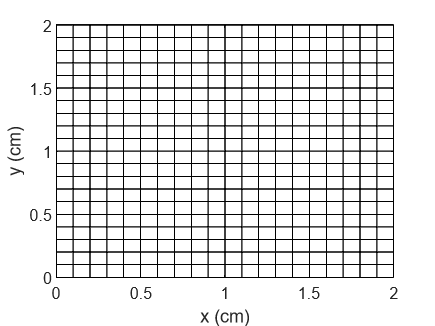

clc
clear

%%% a)

N = 21; % Number of nodes Ni = Nj = N
L = 2; % Length (cm) Lx = Ly = L

l = linspace(0,L,N); % dx = dy = h

h = l(2)-l(1); % coordinate step size
dt = 0.01; % time step size
t = 1:dt:4;

Tcalc = 400*ones(numel(l)+2 , numel(l)+2); % Initial temperature of plate + 2 for environment
a = 0.13/0.11/7.8; % Thermal diffusivity
d = a*(dt/(h^2)); % CFL number

% Left, right, bottom and top sides respectively
Tcalc(1,:) = 10; Tcalc(end,:) = 10; Tcalc(:,1) = 10; Tcalc(:,end) = 10;

for time = dt:dt:4
    Tprev = Tcalc;
    T = Tcalc;
    for i = 2:N+1
        for j = 2:N+1
            x1p = Tprev(i-1,j); x2p = Tprev(i,j); x3p = Tprev(i+1,j);
            y1p = Tprev(i,j-1); y2p = Tprev(i,j); y3p = Tprev(i,j+1);

            x1 = Tcalc(i-1,j); x2 = Tcalc(i,j); x3 = Tcalc(i+1,j);
            y1 = Tcalc(i,j-1); y2 = Tcalc(i,j); y3 = Tcalc(i,j+1);

            T(i,j) = Tprev(i,j) + (d/2)*(x3p + x1p + y3p + y1p - 4*x2p + x3 + x1 + y3 + y1 - 4*y2);
        end
    end
    Tcalc = T;
end
% writematrix(T,'CN')

% plot mesh
[X Y] = meshgrid(l,l);
figure(1)
plot(X,Y,'k',X',Y','k')
xlabel('x (cm)'), ylabel('y (cm)')

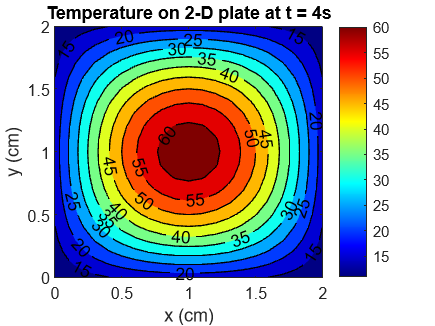

% saveas(gcf,'mesh.jpg')

% plot plate
figure(2)
contourf(X,Y,T(2:22,2:22),'ShowText','on'), colormap(jet)
xlabel('x (cm)'),  ylabel('y (cm)'), colorbar
title('Temperature on 2-D plate at t = 4s')

% saveas(gcf,'CNContour.jpg')


%%% b)
tb = 1:dt:10;
for n = 1:numel(tb)
    Tprev = Tcalc;
    Tb = Tcalc;
    for i = 2:N+1
        for j = 2:N+1
            x1p = Tprev(i-1,j); x2p = Tprev(i,j); x3p = Tprev(i+1,j);
            y1p = Tprev(i,j-1); y2p = Tprev(i,j); y3p = Tprev(i,j+1);

            x1 = Tcalc(i-1,j); x2 = Tcalc(i,j); x3 = Tcalc(i+1,j);
            y1 = Tcalc(i,j-1); y2 = Tcalc(i,j); y3 = Tcalc(i,j+1);

            Tb(i,j) = Tprev(i,j) + (d/2)*(x3p + x1p + y3p + y1p - 4*x2p + x3 + x1 + y3 + y1 - 4*y2);
        end
    end
    Tcalc = Tb;
    TTB(:,:,n) = Tb;
end

for n = 1:numel(tb)
    if (TTB(11,11,n) >= 14.9 &&  TTB(11,11,n) <= 15.1)
        idx(n) = n;
    end
end

idx = nonzeros(idx);
time15C = tb(idx);

fprintf('The center becomes 15°C at t = %4.2f s',time15C(1))

The center becomes 15°C at t = 4.75 s

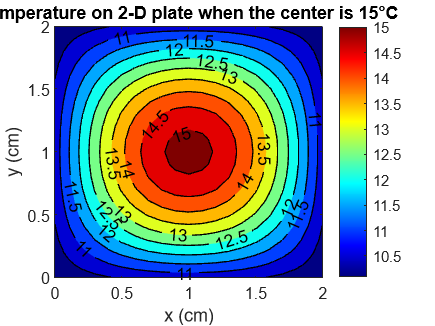


TB = TTB(:,:,idx(1));
% writematrix(TB,'BCN')

figure(3)
contourf(X,Y,TB(2:22,2:22),'ShowText','on'), colormap(jet)
xlabel('x (cm)'),  ylabel('y (cm)'), colorbar
title('Temperature on 2-D plate when the center is 15°C')
saveas(gcf,'BCNContour.jpg')